mu_mesh = .375:.0625:.625;
sigma_mesh = .02:.005:.035;
x = 2;

load('C:\Users\wynga\OneDrive\Desktop\PhD_Research\Data\Mark 1 vs Moneyline\data_struct.mat')

% Checks
for trial_number = 1:30
    for mu_index = 1:length(mu_mesh)
        for sigma_index = 1:length(sigma_mesh)

            % Mark 1
            assert(data_struct(trial_number,mu_index,sigma_index).mark1_system_metrics.dollar_accountability)
            assert(data_struct(trial_number,mu_index,sigma_index).mark1_system_metrics.peer_bets_work)
            assert(data_struct(trial_number,mu_index,sigma_index).mark1_system_metrics.moneyline_works)

            % Money Line
            assert(data_struct(trial_number,mu_index,sigma_index).moneyline_system_metrics.dollar_accountability)
            assert(data_struct(trial_number,mu_index,sigma_index).moneyline_system_metrics.peer_bets_work)
            assert(data_struct(trial_number,mu_index,sigma_index).moneyline_system_metrics.moneyline_works)
        end
    end
end
fprintf('Dollar Accountability: Check\n')

Dollar Accountability: Check


fprintf('Peer Bets Work: Check\n')

Peer Bets Work: Check


fprintf('Moneylines Work: Check\n')

Moneylines Work: Check


% Profit Confidence Intervals

mark1_profit_intervals = cell(length(mu_mesh),length(sigma_mesh));
moneyline_profit_intervals = cell(length(mu_mesh),length(sigma_mesh));

mark1_subjective_expectation_intervals = cell(length(mu_mesh),length(sigma_mesh));
moneyline_subjective_expectation_intervals = cell(length(mu_mesh),length(sigma_mesh));

for mu_index = 1:length(mu_mesh)
    for sigma_index = 1:length(sigma_mesh)

        % Mark 1 Profits
        trial_mark1_metrics = [data_struct(:,mu_index,sigma_index).mark1_system_metrics];
        trial_mark1_profits = [trial_mark1_metrics.total_profit];
        mark1_profit_intervals{mu_index,sigma_index} = mean(trial_mark1_profits)+[-1.96 1.96]*std(trial_mark1_profits)/sqrt(30);

        % Mark 1 Subjective Expectation
        trial_mark1_metrics = [data_struct(:,mu_index,sigma_index).mark1_system_metrics];
        trial_mark1_subjective_expectations = [trial_mark1_metrics.subjective_expectation_created];
        mark1_subjective_expectation_intervals{mu_index,sigma_index} = mean(trial_mark1_subjective_expectations)+[-1.96 1.96]*std(trial_mark1_subjective_expectations)/sqrt(30);

        % Moneyline Profits
        trial_moneyline_metrics = [data_struct(:,mu_index,sigma_index).moneyline_system_metrics];
        trial_moneyline_profits = [trial_moneyline_metrics.total_profit];
        moneyline_profit_intervals{mu_index,sigma_index} = mean(trial_moneyline_profits)+[-1.96 1.96]*std(trial_moneyline_profits)/sqrt(30);

        % Moneyline Subjective Expectation
        trial_moneyline_metrics = [data_struct(:,mu_index,sigma_index).moneyline_system_metrics];
        trial_moneyline_subjective_expectations = [trial_moneyline_metrics.subjective_expectation_created];
        moneyline_subjective_expectation_intervals{mu_index,sigma_index} = mean(trial_moneyline_subjective_expectations)+[-1.96 1.96]*std(trial_moneyline_subjective_expectations)/sqrt(30);
    end
end


% Does the Mark 1 Profit Strictly Dominate the Moneyline Profit
profit_strict_dominance = 1;

for mu_index = 1:length(mu_mesh)
    for sigma_index = 1:length(sigma_mesh)
        profit_local_dominance = min(mark1_profit_intervals{mu_index,sigma_index}) > max(moneyline_profit_intervals{mu_index,sigma_index});
        profit_strict_dominance = profit_strict_dominance & profit_local_dominance;
    end
end

if profit_strict_dominance
    fprintf('Strict Dominance of Mark 1 Profit')
end       

Strict Dominance of Mark 1 Profit



% Does the Mark 1 Subjective Expectation Strictly Dominate the Moneyline Subjective Expectation?
subjective_expecation_strict_dominance = 1;

for mu_index = 1:length(mu_mesh)
    for sigma_index = 1:length(sigma_mesh)
        subjetcive_expectation_local_dominance = min(mark1_subjective_expectation_intervals{mu_index,sigma_index}) > ...
            max(moneyline_subjective_expectation_intervals{mu_index,sigma_index});
        subjective_expecation_strict_dominance = subjective_expecation_strict_dominance & subjetcive_expectation_local_dominance;
    end
end

if subjective_expecation_strict_dominance
    fprintf('Strict Dominance of Mark 1 Subjective Expectation')
end  

Strict Dominance of Mark 1 Subjective Expectation

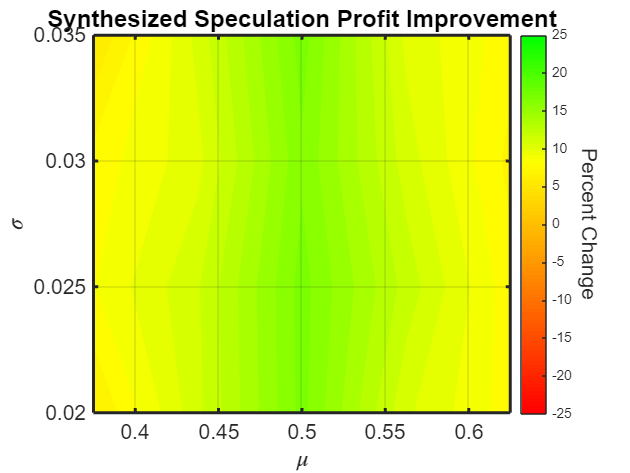

% Contour Plot of Profit from Each System

percent_changes = nan(length(mu_mesh),length(sigma_mesh));
for mu_index = 1:length(mu_mesh)
    for sigma_index = 1:length(sigma_mesh)
        percent_changes(mu_index,sigma_index) = 100*mean(mark1_profit_intervals{mu_index,sigma_index})/mean(moneyline_profit_intervals{mu_index,sigma_index})-100;
    end
end

[X,Y] = meshgrid(mu_mesh,sigma_mesh);
contourf(X',Y',percent_changes,'LineStyle','none')
xlabel('$\mu$','Interpreter','latex')
ylabel('$\sigma$','Interpreter','latex')
title('Synthesized Speculation Profit Improvement')
sexy_plot
colorbar

% Colorbar
the_colorbar = colorbar('Ticks',-25:5:25);
clim([-25 25])
prob_values = 0:.01:1;
red_values = min(3-3*prob_values,1)';
green_values = min(3/2*prob_values,1)';
blue_values = zeros(1,length(prob_values))';
colormap([red_values, green_values, blue_values])
ylabel(the_colorbar,'Percent Change','Rotation',270,'FontSize',14)
hold off


min_profit_percent_change = min(percent_changes,[],'all')

min_profit_percent_change = 5.9732

max_profit_percent_change  = max(percent_changes,[],'all')

max_profit_percent_change = 17.4618

% Contour Plot of Subjective Expectation from Each System

percent_changes = nan(length(mu_mesh),length(sigma_mesh));
for mu_index = 1:length(mu_mesh)
    for sigma_index = 1:length(sigma_mesh)
        percent_changes(mu_index,sigma_index) = 100*mean(mark1_subjective_expectation_intervals{mu_index,sigma_index})...
            /mean(moneyline_subjective_expectation_intervals{mu_index,sigma_index})-100;
    end
end

min_subjective_expectation_percent_change = min(percent_changes,[],'all')

min_subjective_expectation_percent_change = 32.5462

max_subjective_expectation_percent_change  = max(percent_changes,[],'all')

max_subjective_expectation_percent_change = 53.4375

% Generate Values for Results Tables

% Profit
for mu_index = 1:length(mu_mesh)
    my_mark1_string = sprintf('Mu = %.4g',mu_mesh(mu_index));
    my_moneyline_string = sprintf('Mu = %.4g',mu_mesh(mu_index));
    for sigma_index = 1:length(sigma_mesh)
        mark1_profit_interval = mark1_profit_intervals{mu_index,sigma_index};
        lower_value = mark1_profit_interval(1);
        higher_value = mark1_profit_interval(2);
        my_mark1_string = horzcat(my_mark1_string,sprintf(' [%.0f %.0f]',lower_value,higher_value));

        moneyline_profit_interval = moneyline_profit_intervals{mu_index,sigma_index};
        lower_value = moneyline_profit_interval(1);
        higher_value = moneyline_profit_interval(2);
        my_moneyline_string = horzcat(my_moneyline_string,sprintf(' [%.0f %.0f]',lower_value,higher_value));
    end
    fprintf('%s\n',my_mark1_string)
    fprintf('%s\n - \n',my_moneyline_string)
end

Mu = 0.375 [737 754] [924 946] [1101 1136] [1270 1305]


Mu = 0.375 [687 707] [846 870] [1017 1048] [1195 1234]
 - 


Mu = 0.4375 [748 767] [935 952] [1098 1134] [1297 1327]


Mu = 0.4375 [668 688] [833 854] [990 1026] [1163 1193]
 - 


Mu = 0.5 [768 789] [964 978] [1158 1183] [1336 1371]


Mu = 0.5 [653 674] [818 836] [990 1015] [1136 1169]
 - 


Mu = 0.5625 [749 761] [925 946] [1105 1131] [1295 1318]


Mu = 0.5625 [670 687] [820 841] [987 1018] [1166 1193]
 - 


Mu = 0.625 [741 762] [912 934] [1100 1135] [1288 1310]


Mu = 0.625 [682 703] [839 864] [1022 1054] [1178 1218]
 - 



% Subjective Expectation
for mu_index = 1:length(mu_mesh)
    my_mark1_string = sprintf('Mu = %.4g',mu_mesh(mu_index));
    my_moneyline_string = sprintf('Mu = %.4g',mu_mesh(mu_index));
    for sigma_index = 1:length(sigma_mesh)
        mark1_subjective_expectation_interval = mark1_subjective_expectation_intervals{mu_index,sigma_index};
        lower_value = mark1_subjective_expectation_interval(1);
        higher_value = mark1_subjective_expectation_interval(2);
        my_mark1_string = horzcat(my_mark1_string,sprintf(' [%.0f %.0f]',lower_value,higher_value));

        moneyline_subjective_expectation_interval = moneyline_subjective_expectation_intervals{mu_index,sigma_index};
        lower_value = moneyline_subjective_expectation_interval(1);
        higher_value = moneyline_subjective_expectation_interval(2);
        my_moneyline_string = horzcat(my_moneyline_string,sprintf(' [%.0f %.0f]',lower_value,higher_value));
    end
    fprintf('%s\n',my_mark1_string)
    fprintf('%s\n - \n',my_moneyline_string)
end

Mu = 0.375 [717 733] [898 911] [1076 1104] [1257 1294]


Mu = 0.375 [492 544] [618 671] [780 843] [872 938]
 - 


Mu = 0.4375 [747 762] [935 954] [1101 1139] [1285 1324]


Mu = 0.4375 [500 547] [620 683] [710 788] [894 960]
 - 


Mu = 0.5 [756 777] [947 962] [1137 1164] [1317 1350]


Mu = 0.5 [481 533] [613 651] [746 804] [843 895]
 - 


Mu = 0.5625 [748 761] [919 942] [1107 1132] [1286 1313]


Mu = 0.5625 [518 558] [594 649] [757 822] [880 939]
 - 


Mu = 0.625 [715 736] [891 915] [1076 1106] [1246 1274]


Mu = 0.625 [507 560] [626 678] [788 858] [884 955]
 - 


% Money Wastage

mu_mesh = .375:.0625:.625;
sigma_mesh = .02:.005:.035;

mark1_wastage = nan(length(mu_mesh),length(sigma_mesh));
moneyline_wastage = nan(length(mu_mesh),length(sigma_mesh));

for mu_index = 1:length(mu_mesh)
    for sigma_index = 1:length(sigma_mesh)

        % Mark 1 Wastage
        trial_mark1_metrics = [data_struct(:,mu_index,sigma_index).mark1_system_metrics];
        mark1_wastage(mu_index,sigma_index) = trial_mark1_metrics.waste_proportion;

        % Moneyline Profits
        trial_moneyline_metrics = [data_struct(:,mu_index,sigma_index).moneyline_system_metrics];
        moneyline_wastage(mu_index,sigma_index) = trial_moneyline_metrics.waste_proportion;
  
    end
end

min(mark1_wastage,[],'all')

ans = 0.0033

mean(mark1_wastage,'all')

ans = 0.0240

max(mark1_wastage,[],'all')

ans = 0.0632


min(moneyline_wastage,[],'all')

ans = 0.4382

mean(moneyline_wastage,'all')

ans = 0.5189

max(moneyline_wastage,[],'all')

ans = 0.5898


modified_beta_cdf(.68,.625,.03)-modified_beta_cdf(.59,.625,.03)

ans = 0.8518